# Linear Control Design II - Group Work Problem Module 3

## Description

This exercise is based on the work carried out in the Group Work Problem Module 2. For the electro-mechanical system illustrated in Figure 1 and described in Group Work Problem Module 2 the goals for this assignment is: a) linearize the electromagnetic force resulted from the change in current and change in displacement. I.e. $Ki$ and $Ks$; b) derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


c)  investigate the vibrations of the structure when different initial conditions and inputs are present;

d) compare the obtained results from Group Work Module 2 with the results from this Group Work Module.

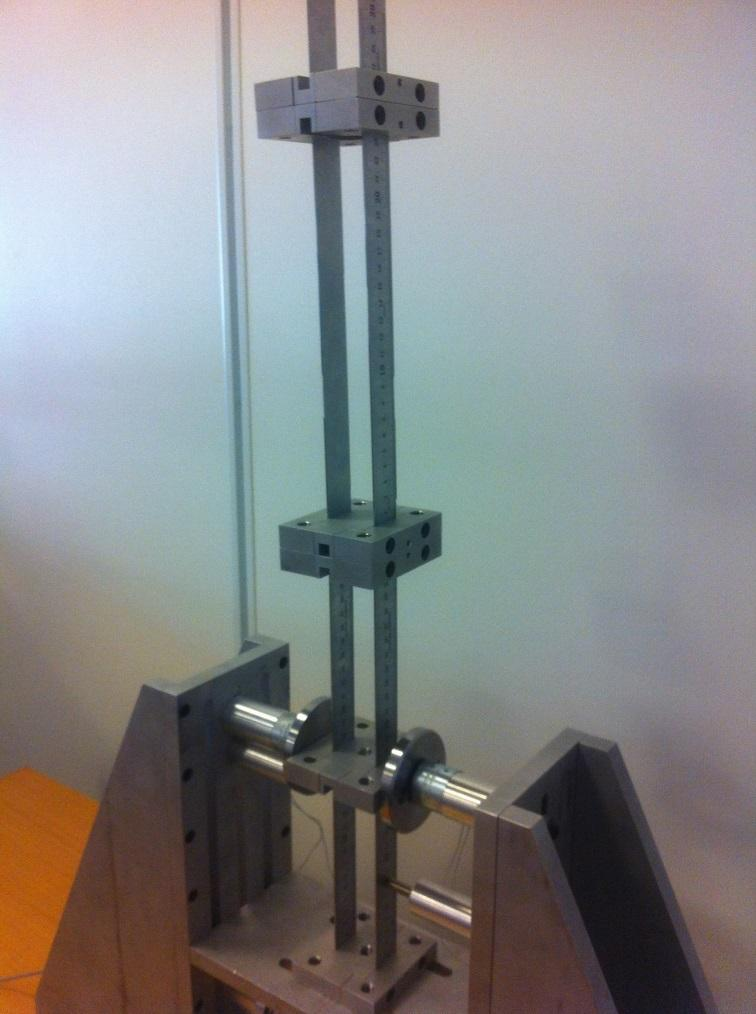


$$Figure\,1:\,Electro-mechanical\,system\,composed\,of\,three\,masses\,interconnected\\ by\,flexible\,beams\,(mechanical parts)\,and\,a\,pair\,of\,electromagnets\,(electrical parts).$$


The parameters needed for the assignment are given below.

**Problem 1**

Linearize the electromagnetic force resulted from the change in current and change in displacement.

Define $Ki$ and $Ks$

clear
% Your solution goes here
% Ki
syms mu N A ib x0
Ki = mu*N^2*A*ib / x0^2

$$Ki = \frac{A\,N^{2}\,\mathrm{ib}\,\mu }{{x_{0}}^{2}}$$

% Ks
Ks = mu*N^2*A*ib^2 / x0^3

$$Ks = \frac{A\,N^{2}\,{\mathrm{ib}}^{2}\,\mu }{{x_{0}}^{3}}$$

**Problem 2**

Derive the SISO state space model ($\textbf{A}$, $\textbf{B}$, $\textbf{C}$ & $\textbf{D}$) for the electro-mechanical system using the state parameters


$$\textbf{x}=[q_1,q_2,q_3,q_4,q_5,q_6,q_7]^T=[i,x_1,\dot{x}_1,x_2,\dot{x}_2,x_3,\dot{x}_3]^T$$


where


$$\dot{\textbf{x}}=\textbf{A}\textbf{x}+\textbf{Bu}\\\textbf{y}=\textbf{C}\textbf{x}+\textbf{Du}$$


% Your solution goes here:
% Upload a picture or fill in your code 
syms i x1 x2 x3 x1_d x2_d x3_d R L Ki Ks k1 k2 k3 m1 m2 m3 u 
q1=i;q2=x1;q3=x1_d;q4=x2;q5=x2_d;q6=x3;q7=x3_d;x=[q1;q2;q3;q4;q5;q6;q7]

$$x = \left(\begin{array}{c} i\\ x_{1}\\ x_{1,d}\\ x_{2}\\ x_{2,d}\\ x_{3}\\ x_{3,d} \end{array}\right)$$

As = [-R/L 0 Ki/L 0 0 0 0;0 0 1 0 0 0 0;-Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0;...
     0 0 0 0 1 0 0; 0 k2/m2 0 -(k2+k3)/m2 0 k3/m2 0; 0 0 0 0 0 0 1; ...
     0 0 0 k3/m3 0 -k3/m3 0]

$$As = \left(\begin{array}{ccccccc} -\frac{R}{L} & 0 & \frac{\mathrm{Ki}}{L} & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0\\ -\frac{\mathrm{Ki}}{m_{1}} & -\frac{\mathrm{Ks}+k_{1}+k_{2}}{m_{1}} & 0 & \frac{k_{2}}{m_{1}} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & \frac{k_{2}}{m_{2}} & 0 & -\frac{k_{2}+k_{3}}{m_{2}} & 0 & \frac{k_{3}}{m_{2}} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & \frac{k_{3}}{m_{3}} & 0 & -\frac{k_{3}}{m_{3}} & 0 \end{array}\right)$$

Bs = [1/L;0;0;0;0;0;0]

$$Bs = \left(\begin{array}{c} \frac{1}{L}\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Cs = [0 1 0 0 0 0 0 ; 0 0 1 0 0 0 0]

Cs =      0     1     0     0     0     0     0
     0     0     1     0     0     0     0


Ds = [0;0]

Ds =      0
     0


x_d = As*x+Bs*u

$$x\_d = \left(\begin{array}{c} \frac{u}{L}-\frac{R\,i}{L}+\frac{\mathrm{Ki}\,x_{1,d}}{L}\\ x_{1,d}\\ \frac{k_{2}\,x_{2}}{m_{1}}-\frac{x_{1}\,\left(\mathrm{Ks}+k_{1}+k_{2}\right)}{m_{1}}-\frac{\mathrm{Ki}\,i}{m_{1}}\\ x_{2,d}\\ \frac{k_{2}\,x_{1}}{m_{2}}+\frac{k_{3}\,x_{3}}{m_{2}}-\frac{x_{2}\,\left(k_{2}+k_{3}\right)}{m_{2}}\\ x_{3,d}\\ \frac{k_{3}\,x_{2}}{m_{3}}-\frac{k_{3}\,x_{3}}{m_{3}} \end{array}\right)$$

y = Cs*x+Ds*u

$$y = \left(\begin{array}{c} x_{1}\\ x_{1,d} \end{array}\right)$$

**Problem 3**

The goal of the problem is to investigate how the structure behaves when $s_0$ (air gap) is varied from 5 mm to 1 mm. The initial conditions of lateral displacements  $x_2(0)$, $x_3(0)$ and  velocities  $\dot{x}_1(0)$, $\dot{x}_2(0)$, $\dot{x}_3(0)$ are zero and kept for all simulation cases. Only the  lateral displacement of the lowest mass $x_1(0)$ is offset by 1 mm from center. Simulate three different values of $s_0$=5 mm, $s_0$=3 mm, $s_0$=1 mm. Explain the simulation results. 

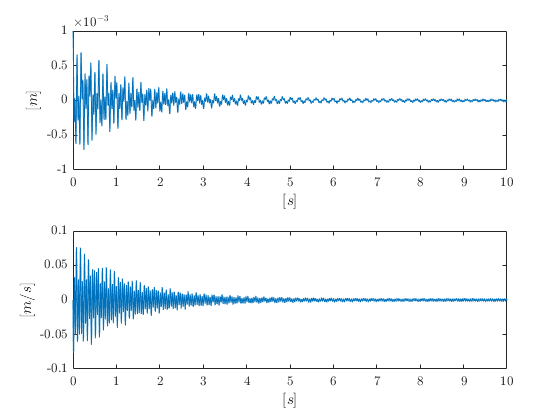

% Your solution goes here:
% Parameters
m1 = 0.712;         % [kg] mass of platform 1
m2 = 0.428;         % [kg] mass of platform 1
m3 = 0.428;         % [kg] mass of platform 1

l = 24e-3; % mm, small
r = 14e-3 / 2;
A = pi*r^2;
R = 148.2;
L = 800e-3; % [H]
iMax = 0.14; % measured at 24v

gam = 0.5;          % bias ratio - normally chosen between 0.2-0.5
ib = iMax*gam;      % Bias current
mu = 4*pi*1e-7;     % Permeability of free space (vacuum)


b = 0.025;          % [m] beam width
h = 1.0e-3;         % [m] beam thickness
E = 2.0e11;         % [N/m2] elasticity modulus of steel
Iz = (b*h^3)/12;    % [m4] area moment of inertia

L1= 0.145;           % [m] length of beam 1
L2= 0.134;           % [m] length of beam 2
L3= 0.229;           % [m] length of beam 3

% Force constants obtained from the linearisation

k1 = 2*12*E*Iz/L1^3;   % [N/m] stiffness of beam 1
k2 = 2*12*E*Iz/L2^3;   % [N/m] stiffness of beam 2
k3 = 2*12*E*Iz/L3^3;   % [N/m] stiffness of beam 3

t = '$[s]$';
v_= '$[V]$';
i_= '$[A]$';
c = '$[C]$';
d = '$[m]$';
v = '$[m/s]$';
a = '$[m/s^2]$';


%

x0 = 5/1000;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*ib^2 / x0^3;

Ax = [-R/L 0 Ki/L 0 0 0 0;0 0 1 0 0 0 0;-Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0;...
     0 0 0 0 1 0 0; 0 k2/m2 0 -(k2+k3)/m2 0 k3/m2 0; 0 0 0 0 0 0 1; ...
     0 0 0 k3/m3 0 -k3/m3 0];
Bx = [1/L;0;0;0;0;0;0];
Cx = [0 1 0 0 0 0 0 ; 0 0 1 0 0 0 0];
Dx = [0;0];
x_0 = [0 1/1000 0 0 0 0 0];
u_0 = 0;

sim('EM_SS_Model')


figure
subplot(2,1,1),plot(y.time,y.signals.values(:,1)),xlabel(t),ylabel(d)
subplot(2,1,2),plot(y.time,y.signals.values(:,2)),xlabel(t),ylabel(v)

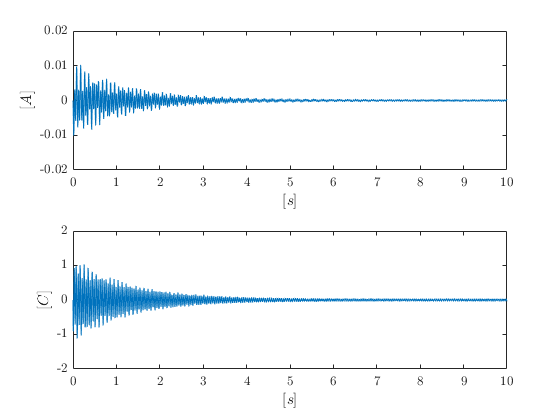

figure
subplot(2,1,1),plot(x.time,x.signals.values(:,1)),xlabel(t),ylabel(i_)
subplot(2,1,2),plot(x_d.time,x_d.signals.values(:,1)),xlabel(t),ylabel(c)

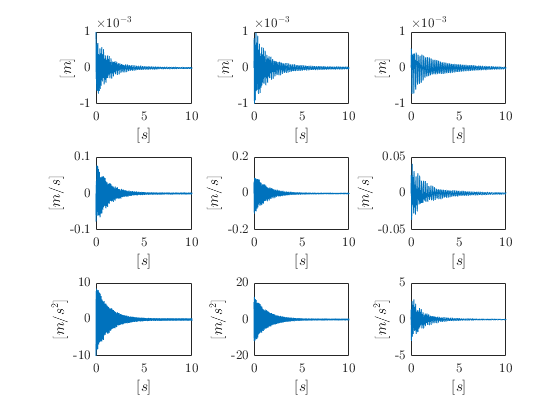

figure
subplot(3,3,1),plot(x.time,x.signals.values(:,2)),xlabel(t),ylabel(d)
subplot(3,3,4),plot(x.time,x.signals.values(:,3)),xlabel(t),ylabel(v)
subplot(3,3,7),plot(x_d.time,x_d.signals.values(:,3)),xlabel(t),ylabel(a)
subplot(3,3,2),plot(x.time,x.signals.values(:,4)),xlabel(t),ylabel(d)
subplot(3,3,5),plot(x.time,x.signals.values(:,5)),xlabel(t),ylabel(v)
subplot(3,3,8),plot(x_d.time,x_d.signals.values(:,5)),xlabel(t),ylabel(a)
subplot(3,3,3),plot(x.time,x.signals.values(:,6)),xlabel(t),ylabel(d)
subplot(3,3,6),plot(x.time,x.signals.values(:,7)),xlabel(t),ylabel(v)
subplot(3,3,9),plot(x_d.time,x_d.signals.values(:,7)),xlabel(t),ylabel(a)

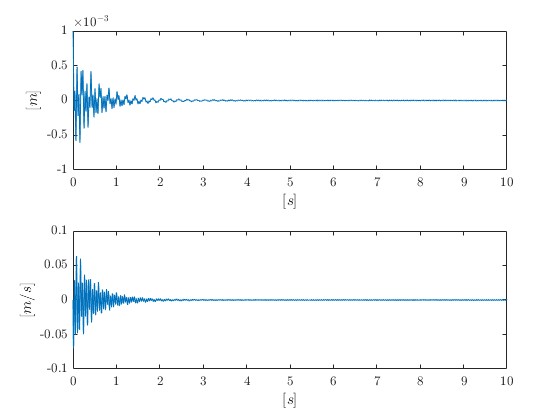

x0 = 3/1000;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*ib^2 / x0^3;

Ax = [-R/L 0 Ki/L 0 0 0 0;0 0 1 0 0 0 0;-Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0;...
     0 0 0 0 1 0 0; 0 k2/m2 0 -(k2+k3)/m2 0 k3/m2 0; 0 0 0 0 0 0 1; ...
     0 0 0 k3/m3 0 -k3/m3 0];
Bx = [1/L;0;0;0;0;0;0];
Cx = [0 1 0 0 0 0 0 ; 0 0 1 0 0 0 0];
Dx = [0;0];

x_0 = [0 1/1000 0 0 0 0 0];
u_0 = 0;

sim('EM_SS_Model')


figure
subplot(2,1,1),plot(y.time,y.signals.values(:,1)),xlabel(t),ylabel(d)
subplot(2,1,2),plot(y.time,y.signals.values(:,2)),xlabel(t),ylabel(v)

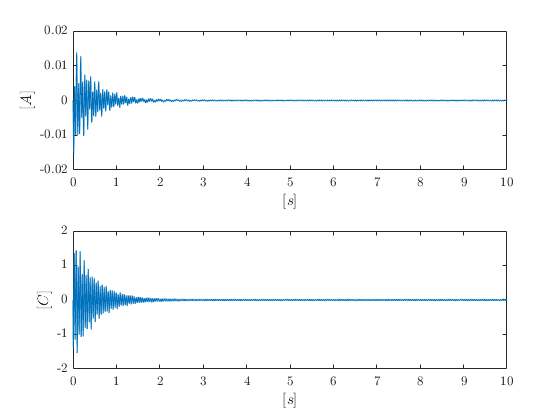

figure
subplot(2,1,1),plot(x.time,x.signals.values(:,1)),xlabel(t),ylabel(i_)
subplot(2,1,2),plot(x_d.time,x_d.signals.values(:,1)),xlabel(t),ylabel(c)

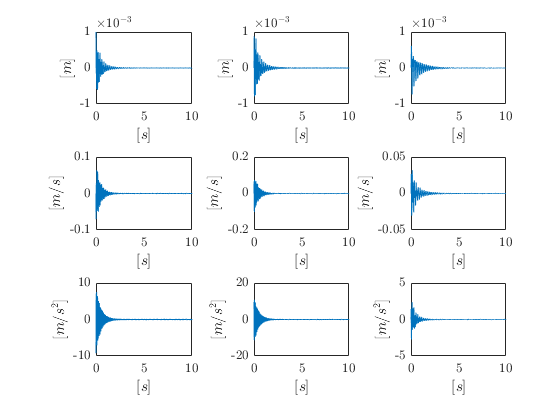

figure
subplot(3,3,1),plot(x.time,x.signals.values(:,2)),xlabel(t),ylabel(d)
subplot(3,3,4),plot(x.time,x.signals.values(:,3)),xlabel(t),ylabel(v)
subplot(3,3,7),plot(x_d.time,x_d.signals.values(:,3)),xlabel(t),ylabel(a)
subplot(3,3,2),plot(x.time,x.signals.values(:,4)),xlabel(t),ylabel(d)
subplot(3,3,5),plot(x.time,x.signals.values(:,5)),xlabel(t),ylabel(v)
subplot(3,3,8),plot(x_d.time,x_d.signals.values(:,5)),xlabel(t),ylabel(a)
subplot(3,3,3),plot(x.time,x.signals.values(:,6)),xlabel(t),ylabel(d)
subplot(3,3,6),plot(x.time,x.signals.values(:,7)),xlabel(t),ylabel(v)
subplot(3,3,9),plot(x_d.time,x_d.signals.values(:,7)),xlabel(t),ylabel(a)

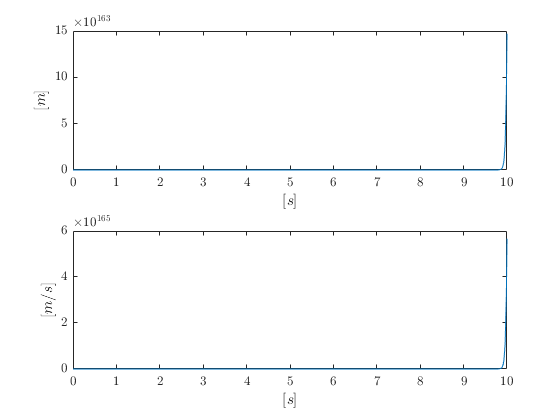

x0 = 1/1000;          % displacement operation point
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*ib^2 / x0^3;

Ax = [-R/L 0 Ki/L 0 0 0 0;0 0 1 0 0 0 0;-Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0;...
     0 0 0 0 1 0 0; 0 k2/m2 0 -(k2+k3)/m2 0 k3/m2 0; 0 0 0 0 0 0 1; ...
     0 0 0 k3/m3 0 -k3/m3 0];
Bx = [1/L;0;0;0;0;0;0];
Cx = [0 1 0 0 0 0 0 ; 0 0 1 0 0 0 0];
Dx = [0;0];

x_0 = [0 1/1000 0 0 0 0 0];
u_0 = 0;

sim('EM_SS_Model')


figure
subplot(2,1,1),plot(y.time,y.signals.values(:,1)),xlabel(t),ylabel(d)
subplot(2,1,2),plot(y.time,y.signals.values(:,2)),xlabel(t),ylabel(v)

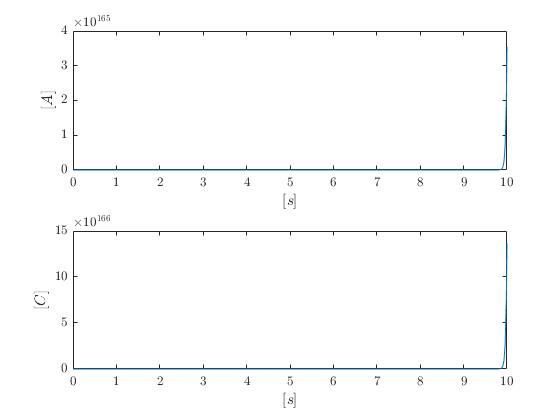

figure
subplot(2,1,1),plot(x.time,x.signals.values(:,1)),xlabel(t),ylabel(i_)
subplot(2,1,2),plot(x_d.time,x_d.signals.values(:,1)),xlabel(t),ylabel(c)

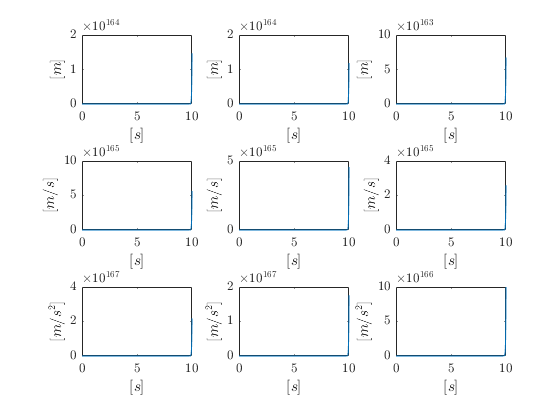

figure
subplot(3,3,1),plot(x.time,x.signals.values(:,2)),xlabel(t),ylabel(d)
subplot(3,3,4),plot(x.time,x.signals.values(:,3)),xlabel(t),ylabel(v)
subplot(3,3,7),plot(x_d.time,x_d.signals.values(:,3)),xlabel(t),ylabel(a)
subplot(3,3,2),plot(x.time,x.signals.values(:,4)),xlabel(t),ylabel(d)
subplot(3,3,5),plot(x.time,x.signals.values(:,5)),xlabel(t),ylabel(v)
subplot(3,3,8),plot(x_d.time,x_d.signals.values(:,5)),xlabel(t),ylabel(a)
subplot(3,3,3),plot(x.time,x.signals.values(:,6)),xlabel(t),ylabel(d)
subplot(3,3,6),plot(x.time,x.signals.values(:,7)),xlabel(t),ylabel(v)
subplot(3,3,9),plot(x_d.time,x_d.signals.values(:,7)),xlabel(t),ylabel(a)

**Problem 4**

What is the maximum lateral displacement experienced by the three masses when an initial condition of velocity of 5 mm/s acts on mass 3, assuming $s_0$=2 mm?

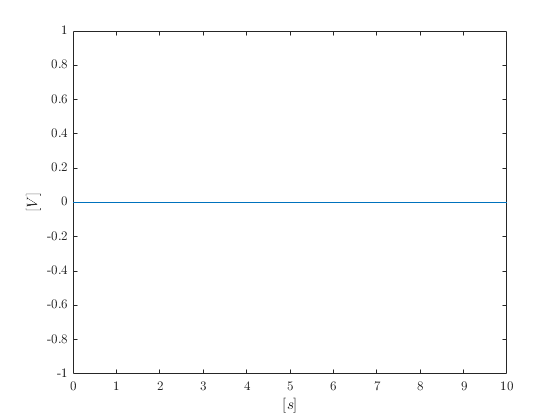

% Your solution goes here:
x0 = 2/1000;
N = sqrt(L*2*x0 / (mu*A)); % estimate number of windings based on above formular
Ki = mu*N^2*A*ib / x0^2;
Ks = -mu*N^2*A*ib^2 / x0^3;
Ax = [-R/L 0 Ki/L 0 0 0 0;0 0 1 0 0 0 0;-Ki/m1 -(k1+k2+Ks)/m1 0 k2/m1 0 0 0;...
     0 0 0 0 1 0 0; 0 k2/m2 0 -(k2+k3)/m2 0 k3/m2 0; 0 0 0 0 0 0 1; ...
     0 0 0 k3/m3 0 -k3/m3 0];
Bx = [1/L;0;0;0;0;0;0];
Cx = [0 1 0 0 0 0 0 ; 0 0 1 0 0 0 0];
Dx = [0;0];

x_0 = [0 0 0 0 0 0 5/1000];
u_0 = 0;

sim('EM_SS_Model')

figure
plot(u.time,u.signals.values),xlabel(t),ylabel(v_)

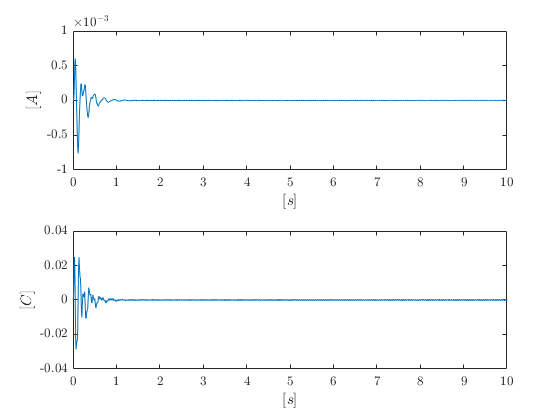

figure
subplot(2,1,1),plot(x.time,x.signals.values(:,1)),xlabel(t),ylabel(i_)
subplot(2,1,2),plot(x_d.time,x_d.signals.values(:,1)),xlabel(t),ylabel(c)

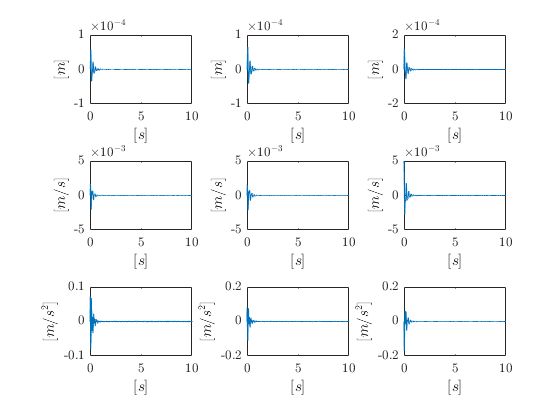

figure
subplot(3,3,1),plot(x.time,x.signals.values(:,2)),xlabel(t),ylabel(d)
subplot(3,3,4),plot(x.time,x.signals.values(:,3)),xlabel(t),ylabel(v)
subplot(3,3,7),plot(x_d.time,x_d.signals.values(:,3)),xlabel(t),ylabel(a)
subplot(3,3,2),plot(x.time,x.signals.values(:,4)),xlabel(t),ylabel(d)
subplot(3,3,5),plot(x.time,x.signals.values(:,5)),xlabel(t),ylabel(v)
subplot(3,3,8),plot(x_d.time,x_d.signals.values(:,5)),xlabel(t),ylabel(a)
subplot(3,3,3),plot(x.time,x.signals.values(:,6)),xlabel(t),ylabel(d)
subplot(3,3,6),plot(x.time,x.signals.values(:,7)),xlabel(t),ylabel(v)
subplot(3,3,9),plot(x_d.time,x_d.signals.values(:,7)),xlabel(t),ylabel(a)

x1_max = max(x.signals.values(:,2))

x1_max =    5.6973e-05


x2_max = max(x.signals.values(:,4))

x2_max =    6.5319e-05


x3_max = max(x.signals.values(:,6))

x3_max =    0.00011952


**Problem 5**

 A step function $u(t)$=10 V is send to the electromagnets, assuming all initial conditions of lateral displacement, velocity and current nill. How will the three masses vibrate and how will the current change, i.e. amplitudes and frequencies. 

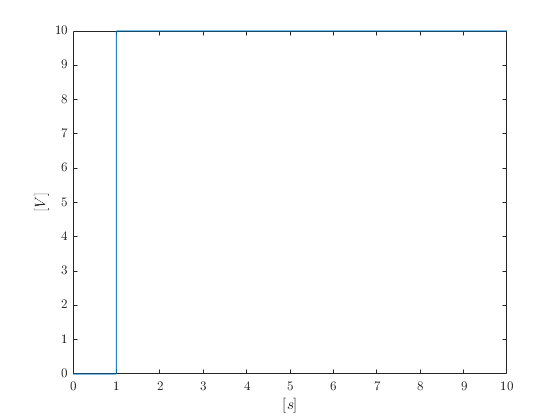

% Your solution goes here:
x_0 = [0 0 0 0 0 0 0];
u_0 = 10;

sim('EM_SS_Model')

figure
plot(u.time,u.signals.values),xlabel(t),ylabel(v_)

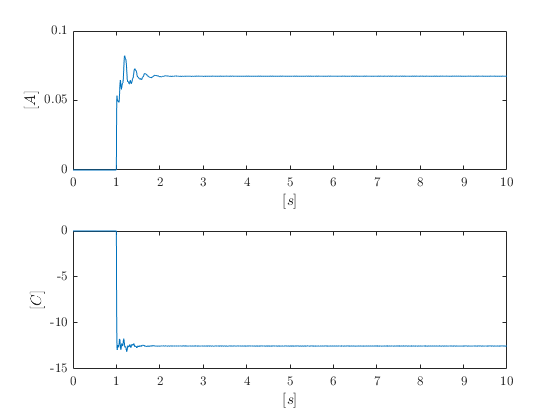

figure
subplot(2,1,1),plot(x.time,x.signals.values(:,1)),xlabel(t),ylabel(i_)
subplot(2,1,2),plot(x_d.time,x_d.signals.values(:,1)),xlabel(t),ylabel(c)

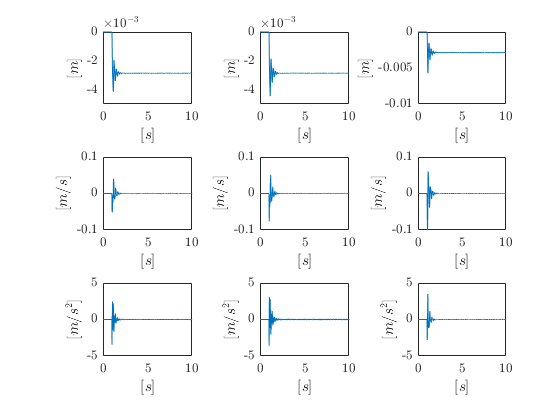

figure
subplot(3,3,1),plot(x.time,x.signals.values(:,2)),xlabel(t),ylabel(d)
subplot(3,3,4),plot(x.time,x.signals.values(:,3)),xlabel(t),ylabel(v)
subplot(3,3,7),plot(x_d.time,x_d.signals.values(:,3)),xlabel(t),ylabel(a)
subplot(3,3,2),plot(x.time,x.signals.values(:,4)),xlabel(t),ylabel(d)
subplot(3,3,5),plot(x.time,x.signals.values(:,5)),xlabel(t),ylabel(v)
subplot(3,3,8),plot(x_d.time,x_d.signals.values(:,5)),xlabel(t),ylabel(a)
subplot(3,3,3),plot(x.time,x.signals.values(:,6)),xlabel(t),ylabel(d)
subplot(3,3,6),plot(x.time,x.signals.values(:,7)),xlabel(t),ylabel(v)
subplot(3,3,9),plot(x_d.time,x_d.signals.values(:,7)),xlabel(t),ylabel(a)

**Problem 6**

Compare the obtained results from Group Work Module 2 (problems 4, 5 and 6) with the results from this Group Work Module (problems 3, 4 and 5).

% Your solution goes here:

The results are identical